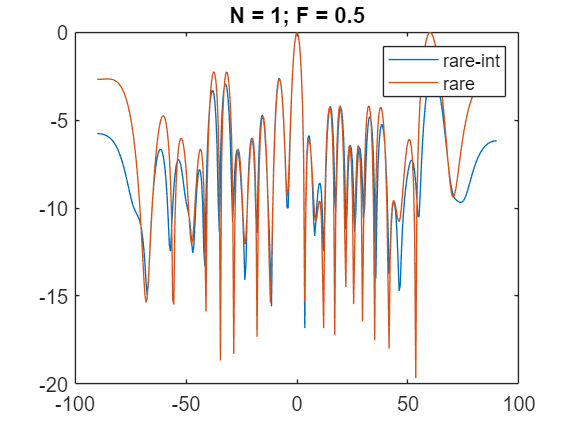

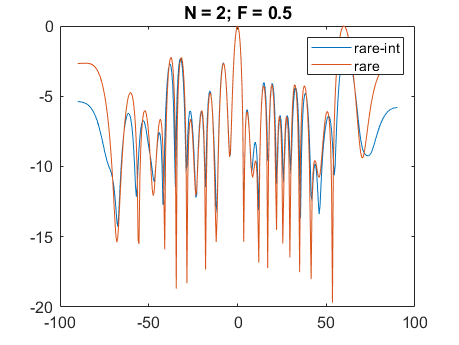

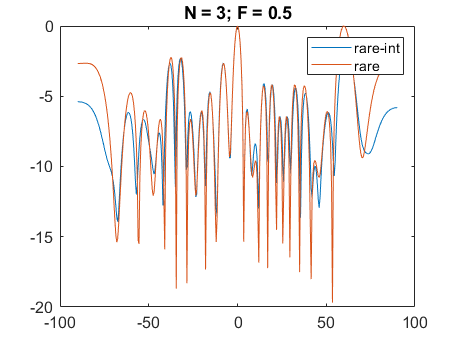

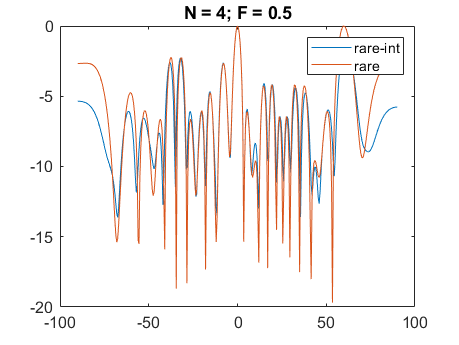

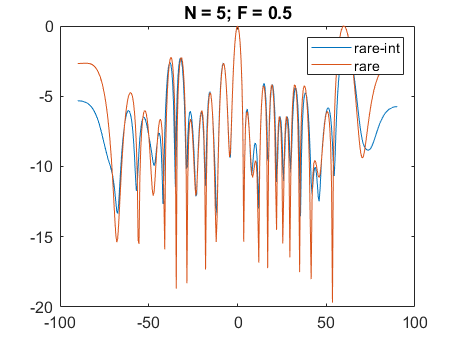

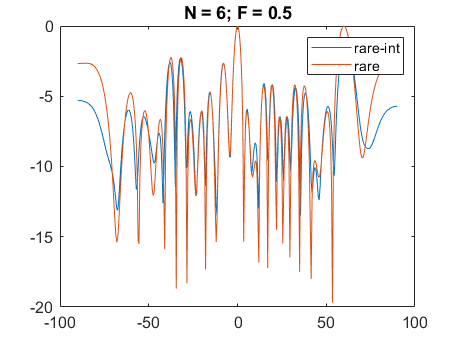

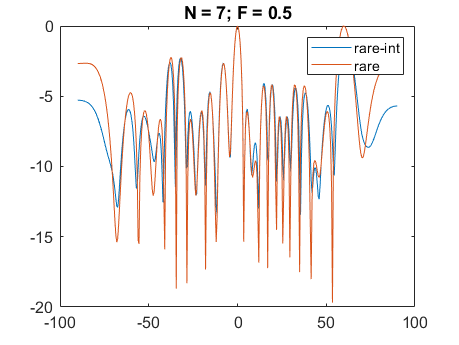

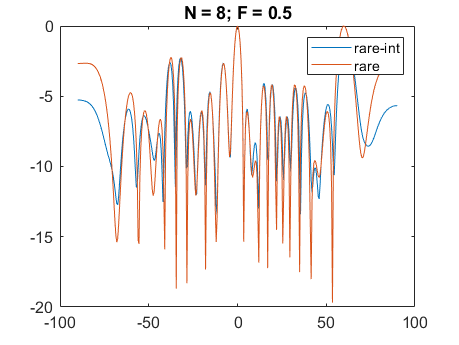

clear;clc;
% close all;
% 
c = physconst("Lightspeed");
% freq params
f = 3e9; % 3 GHz
w = 2*pi*f;
lam = freq2wavelen(f);
k = 2*pi/lam;
% array params
xmin = 0;xmax = 30;
dOk = lam/2;
% NOk = round((xmax-xmin)/dOk);
dxOk = dOk*(xmin:1:xmax)';

dxRare = dOk*[0 4 7 10 12 14 15 16 18 20 23 26 30]';

% dxOk = dxOk - max(dxOk)/2;
aimAngles = [0 60];
aimAmps   = [0 0];

% % % 
valuesOk = distribution_former(dxOk,f,aimAngles, aimAmps);
valuesRare = distribution_former(dxRare,f,aimAngles, aimAmps);

valuesRare2 = [
valuesRare(1)
zeros(3,1)
valuesRare(2)
zeros(2,1)
valuesRare(3)
zeros(2,1)
valuesRare(4)
zeros(1,1)
valuesRare(5)
zeros(1,1)
valuesRare(6:8)
zeros(1,1)
valuesRare(9)
zeros(1,1)
valuesRare(10)
zeros(2,1)
valuesRare(11)
zeros(2,1)
valuesRare(12)
zeros(3,1)
valuesRare(13)
];


[rstOk,theta] = aec_simulation(valuesOk, dxOk,f);
rstOkT = pow2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
rstRare = aec_simulation(valuesRare, dxRare,f);
rstRareT = pow2db(abs(rstRare));rstRareT = rstRareT - max(rstRareT);

for iN = 1:15
interpN = iN;
interpF = 0.5;
valuesRare3 = interp(valuesRare2,2,interpN,interpF);
dxRare3 = linspace(dOk*xmin,dOk*xmax,length(valuesRare3))';
[rstRare3,theta] = aec_simulation(valuesRare3, dxRare3,f);
rstRareT3 = pow2db(abs(rstRare3));rstRareT3 = rstRareT3 - max(rstRareT3);
figure
plot(theta, rstRareT3,theta, rstRareT)
title(['N = ' num2str(interpN) '; F = ' num2str(interpF)])
legend("rare-int","rare")
end



% plot(theta, rstRareT)
% axis([-90 90 -40 1])
% title("rare")
% 
% plot(theta, rstRareT3)
% axis([-90 90 -40 1])
% title("rare3")

% 
% figure
% plot(theta, rstRareT3-rstRareT)
